# Atividade 08_01

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Sharpening no domínio da frequência    

Lembrando:

- O sharpening consiste no realce das bordas da imagem.

- Ao contrário do domínio espacial, onde é feita a convolução da imagem com a máscara do filtro, no domínio da frequência o processo de filtragem do espectro envolve a multiplicação e é pixel a pixel.

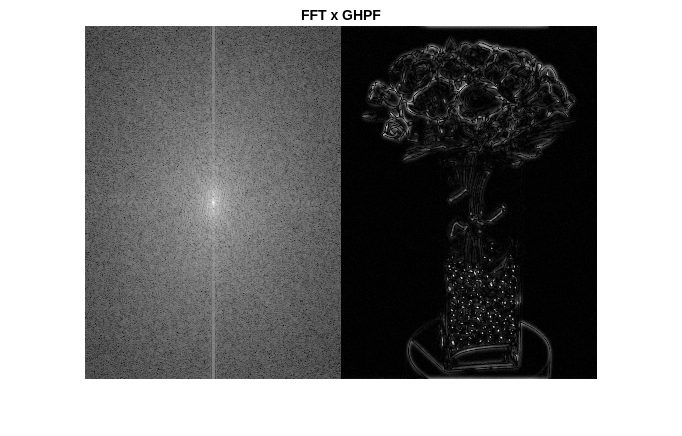

f = imread("flowervaseg.png");
fd = double(f);

[nr, nc] = size(f);

H = fspecial('gaussian',[nr nc], 25);
H = mat2gray(H);
H = 1 - H;

F = fftshift(fft2(fd));

gpa = F .* H;
gpa = ifft2(gpa);
gpa = mat2gray(abs(gpa));

fghpf = f + im2uint8(gpa);

figure, imshowpair(mat2gray(log(1+abs(F))), gpa, "montage")
title('FFT x GHPF')

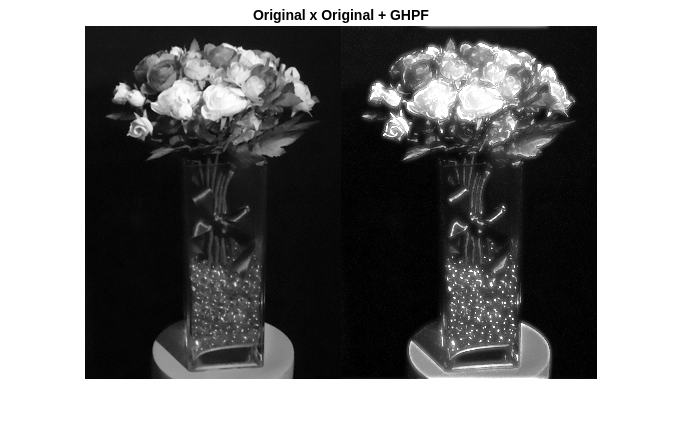


figure, imshowpair(f, fghpf, "montage")
title("Original x Original + GHPF") 